# Separar dos elements per Watershed

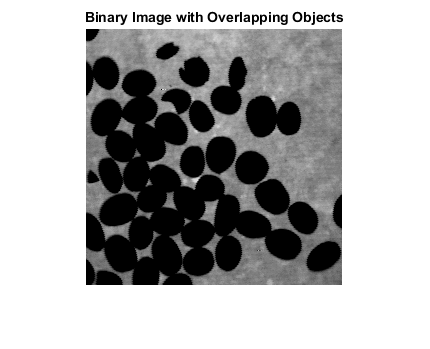

%creating a binary image with two overlapping circular objects
im = imread('cafe.tif');
imshow(im)
title('Binary Image with Overlapping Objects')

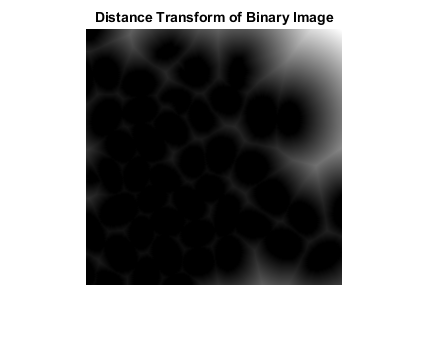

%computing distance transform of the image
D = bwdist(~im);
imshow(D,[])
title('Distance Transform of Binary Image')


%invers of the distance transform to find the local minim
D = -D;
imshow(D,[])
title('Complement of Distance Transform')

%Calculate the watershed transform. Pixels outside de ROI are 0
L = watershed(D);
L(~im) = 0;

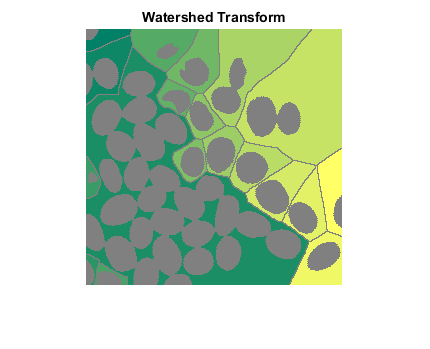

%Displaying the resulting label matrix
rgb = label2rgb(L,'summer',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')